# Introduction: Frequency Method

## Phase margin and Gain margin

The gain margin is defined as the change in open-loop gain required to make the closed-loop system unstable.

The phase margin is defined as the change in open-loop phase shift required to make the closed-loop system unstable. 

The closed-loop system's phase margin is the additional amount of phase lag that is required for the open-loop system's phase to reach -180 degrees at the frequency where the open-loop system's magnitude is 0 dB, the frequency is called gain crossing frequency.

the gain margin is the additional amount of gain (usually in dB) required for the open-loop system's magnitude to reach 0 dB at the frequency where the open-loop system's phase equals -180 degrees. The frequency si called phase crossing frequency

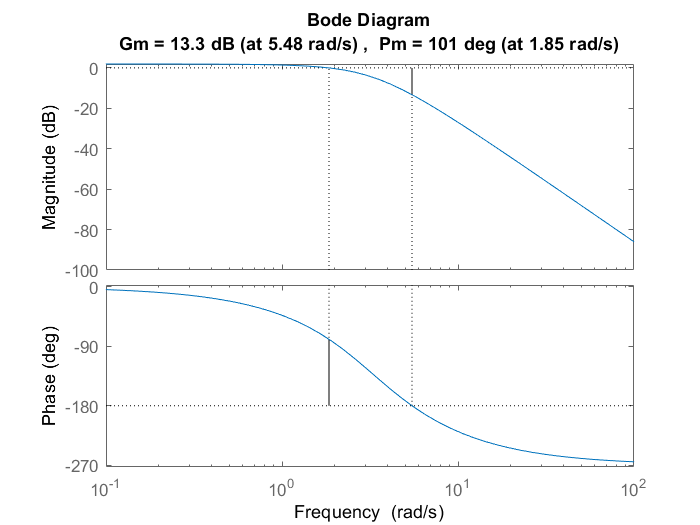

% find the gain and phase margin of a system
s = tf('s');
G = 50/(s^3 + 9*s^2 + 30*s +40);
margin(G)

## Bandwidth Frequency

The bandwidth frequency is defined as the frequency at which the closed-loop magnitude drops 3 dB below its magnitude at DC (magnitude as the frequency approaches 0). However, when we design via frequency response, we are interested in predicting the closed-loop behavior from the open-loop response. Therefore, we will use a second-order system approximation and say that the bandwidth frequency equals the frequency at which the open-loop magnitude response is between -6 and -7.5 dB, assuming the open-loop phase response is between -135 deg and -225 deg. For a complete derivation of this approximation, consult your textbook.

## Nyquist Plot

The Cauchy criterion (from complex analysis) states that when taking a closed contour in the complex plane, and mapping it through a complex function , the number of times that the plot of G(s) encircles the origin is equal to the number of zeros of  G(s) enclosed by the frequency contour minus the number of poles of  G(s)enclosed by the frequency contour. Encirclements of the origin are counted as positive if they are in the same direction as the original closed contour or negative if they are in the opposite direction.

For stablility, we care whether is encircles by -1.

**Note: The MATLAB **`nyquist`** command does not provide an adequate representation for systems that have open-loop poles on the imaginary axis.** 

s = tf('s');
G = 1/(s^2 + 2*s + 3)


G =
 
        1
  -------------
  s^2 + 2 s + 3
 
Continuous-time transfer function.



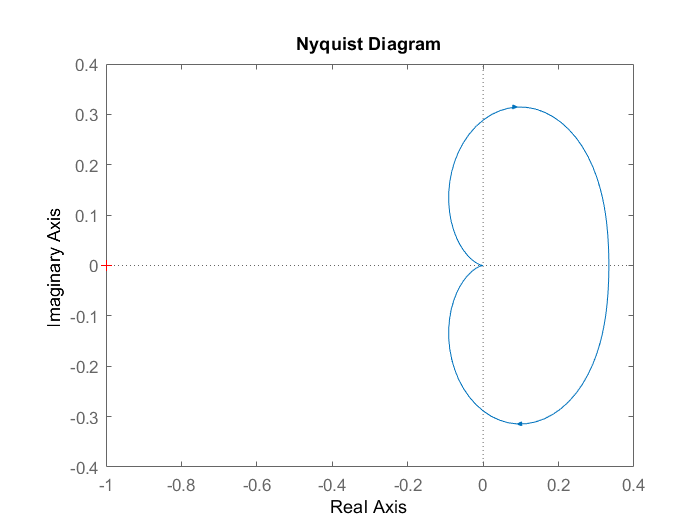

nyquist(G)

## Closed Loop Performance from Bode Plot

In order to predict closed-loop performance from open-loop frequency response, we need to make a few assumptions:

- The system must be stable in open-loop if we are going to use Bode plots for our design.

- For canonical second-order systems, the closed-loop damping ratio is approximately equal to the phase margin divided by 100 if the phase margin is between 0 and 60 degrees. We can use this concept with caution if the phase margin is greater than 60 degrees.

- For canonical second-order systems, a relationship between damping ratio, bandwidth frequency, and settling time is given by an equation described on the [Extras: Bandwidth](http://ctms.engin.umich.edu/CTMS/index.php?aux=Extras_wbw) page.

- A very rough estimate that you can use, is that the bandwidth is approximately equal to the natural frequency.

## Design Example

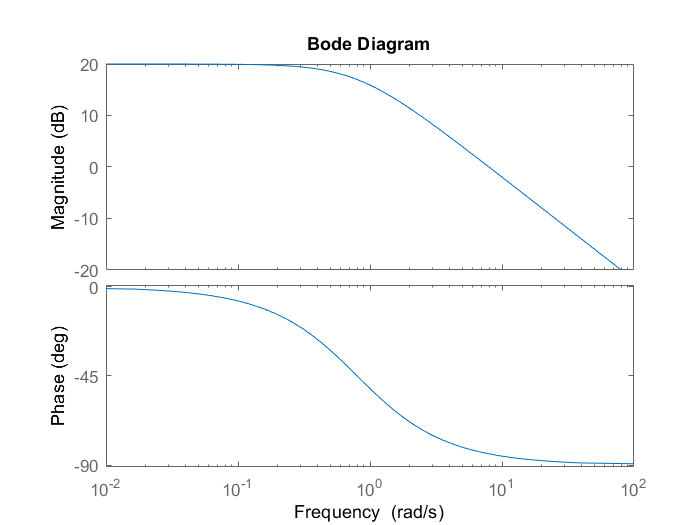

% Design criteria
% 1. zero-steady state error
% 2. Overshoot less than 40%
% 3. Settling time less than 2 sec

s = tf('s');
G = 10/(1.25*s + 1);
bode(G);

The damping ratio corresponding to this overshoot is approximately 0.28. Therefore, our phase margin should be at least 30 degrees. We must have a bandwidth frequency greater than or equal to 12 if we want our settling time to be less than 1.75 seconds which meets the design specifications. Moreover, zero-steady state error means that our controller should have an integration term.

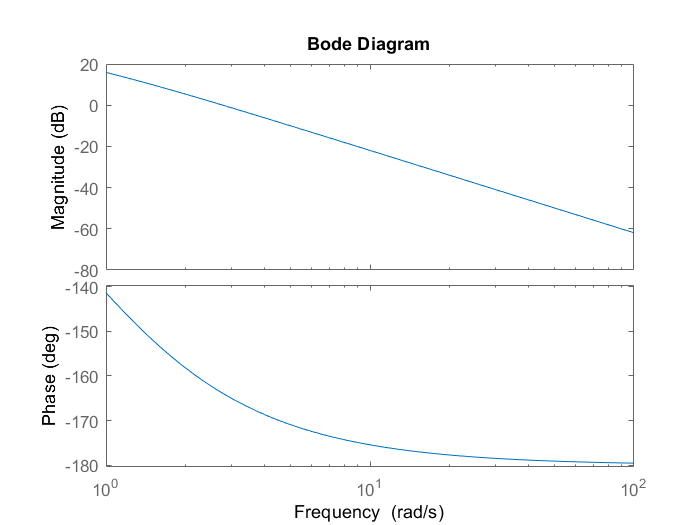

% add an integral control, and see the result
C = 1/s;
bode(C*G, logspace(0, 2));

Phase margin is too small, and we need some phase lead in the controller

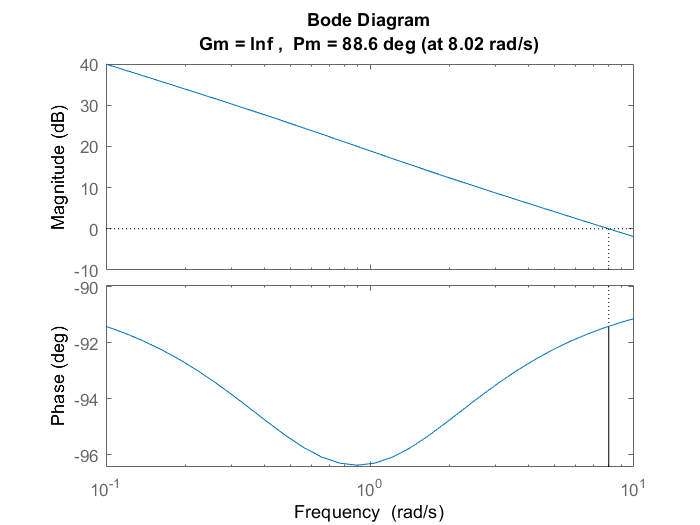

C = (s+1)/s;
bode(C*G, logspace(0, 2));margin(C*G);

Now phase margin is ok, and bandwidth frequency is about 11 rad/s (at -6 db). Give a large gain to increase the bandwidth frequency without chaning much on the phase plot

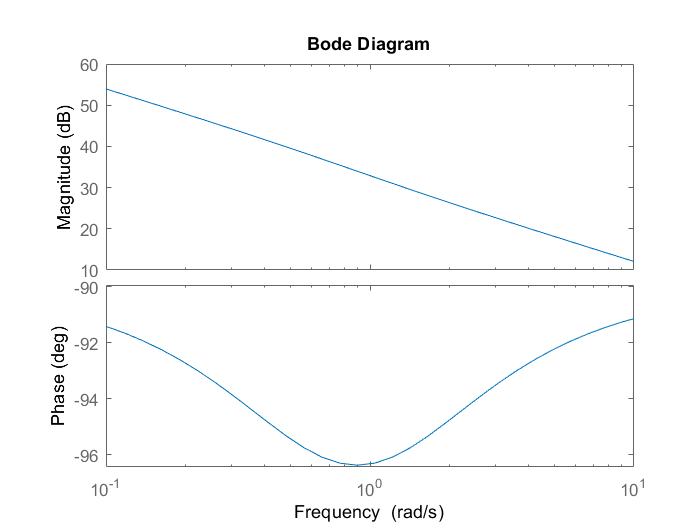

C = 5*((s + 1)/s);
bode(C*G);

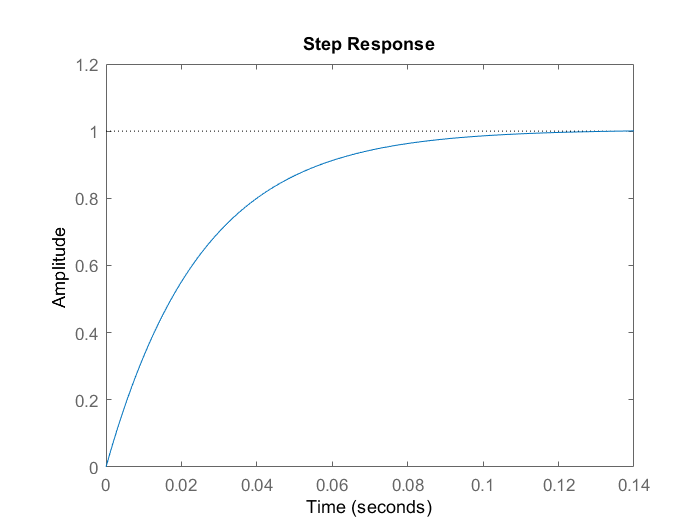

sys = feedback(C*G, 1);
step(sys)